# **demo02 of Im2mesh package**

demo02 - Demonstrate function im2meshBuiltIn, which use matlab built-in function generateMesh as mesh generator.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com   [Project website](https://github.com/mjx888/im2mesh)   [List of demo](https://mjx888.github.io/im2mesh_demo_html/demo_list.html)

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

**To use function im2meshBuiltIn, you need to install MATLAB Partial Differential Equation Toolbox.**

## im2meshBuiltIn

Let's start demo02. We'll demostate the usage of function im2meshBuiltIn.

Import image.

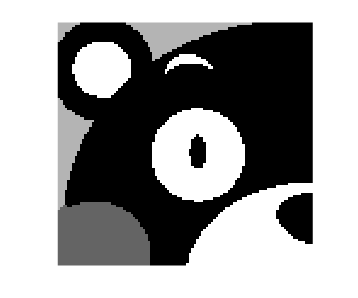

im = imread('kumamon.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Let's use function im2meshBuiltIn to generate meshes based on the kumamon image. We will use default settings. Note that function im2meshBuiltIn is quite similar to function im2mesh. Just the mesh generator is different. Function im2meshBuiltIn use matlab built-in function generateMesh ([https://www.mathworks.com/help/pde/ug/pde.pdemodel.generatemesh.html](https://www.mathworks.com/help/pde/ug/pde.pdemodel.generatemesh.html)) as mesh generator. 

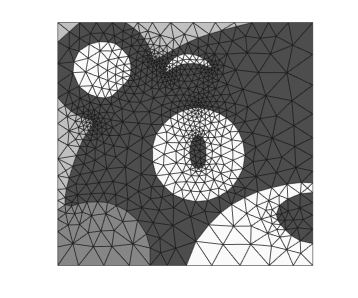

[ vert, tria, tnum ] = im2meshBuiltIn( im );
plotMeshes( vert, tria, tnum )

We can get the mean value of Q.

mean(triscr2( vert, tria ))

ans = 0.9533

Wonderful! Let's check the total number of triangles in the mesh.

size( tria, 1 )

ans = 1358

## Parameters of function im2meshBuiltIn

There're two ways to call function im2meshBuiltIn.

Variable opt means options. It's a structure array used to stored input parameters for function. We can take a look at the default value of opt.

The meaning of these parameters are listed the file "im2meshBuiltIn.m" and "Im2mesh functions and parameters.pdf". Please refer to "Im2mesh_GUI Tutorial.pdf" about how to choose the value of these parameters. You can change these default values by editting sub-function setOption in "im2meshBuiltIn.m".

## **Quadratic element**

Function im2meshBuiltIn can also generate quadratic element via the following syntax.

Ouput variables - vert, tria, tnum define **linear elements.**

Ouput variables - vert2, tria2, tnum define **quadratic elements.**

Their meanings have been listed in demo01.

## MATLAB PDE model object

im2meshBuiltIn can return Matlab PDE model objects. 

If you are familiar with MATLAB PDE Toolbox, you can use PDE model object to solve PDE.

model1 - PDE model object with linear elements

model2 - PDE model object with 2nd order elements

PDE model object: https://www.mathworks.com/help/pde/ug/pde.pdemodel.html

## Example 1

Let's show some examples with different opt.

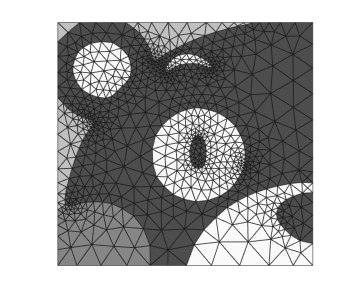

% example 1
opt = [];               % reset opt
opt.tolerance = 0.2;
opt.hmin = 1;         %  Min Mesh Edge Length
[ vert, tria, tnum ] = im2meshBuiltIn( im, opt );

plotMeshes( vert, tria, tnum );

## Example 2

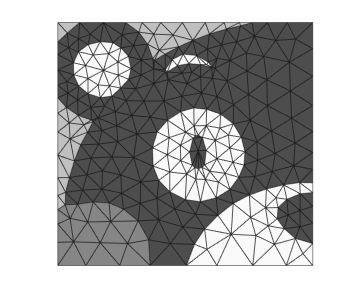

% example 2
opt = [];               % reset opt
opt.tolerance = 0.2;
opt.hmin = 5;           %  Min Mesh Edge Length

[ vert, tria, tnum ] = im2meshBuiltIn( im, opt );
plotMeshes( vert, tria, tnum );

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo